This script collects fitting parameter from acquisitions that I want to know what the fitting parameters (tau1, tau2, p1, p2, photoncount, lifetime, chi square).

Run this script.

If the parameter_collection term is 1, then the parameters listed here will be collected every time the fitting function is run.

The dateset used to collect is in /Users/pingchuanma/Desktop/ChenLab_Data/simulation_ACh_20220722/0831HEKAchsensor003.

I'm using the cycle position 2 of this dataset.

The 100 uM ACh condition is from the epoch 3, acq 63-119.

parameter_collection=1; % either 1 or other numbers

lifetimes_collection=[];
photoncounts=[];
mean_tau=[];
empirical_lft=[];
betahats=[];
Acq_nums=[];
chisqs=[];



global lifetimes_collection photoncounts mean_tau empirical_lft betahats Acq_nums parameter_collection chisqs

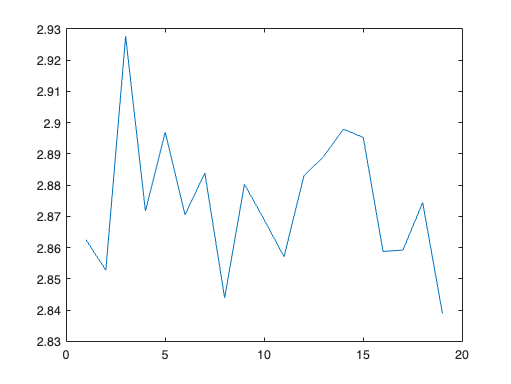

% after the parameter collection

tau1s=betahats(2,:)*12.5/256;
tau2s=betahats(4,:)*12.5/256;
pop1s=betahats(1,:);
pop2s=betahats(2,:);
p1s=zeros(1,length(pop1s));
p1s=zeros(1,length(pop1s));
for i=1:length(pop1s)
    p1s(i)=pop1s(i)/(pop1s(i)+pop2s(i));
    p2s(i)=1-p1s(i);
end

figure
plot(tau1s)

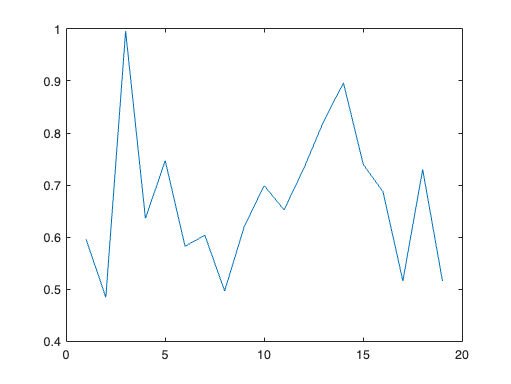


figure
plot(tau2s)

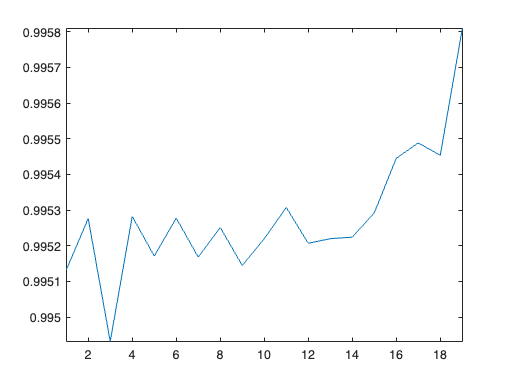


figure
plot(p1s)

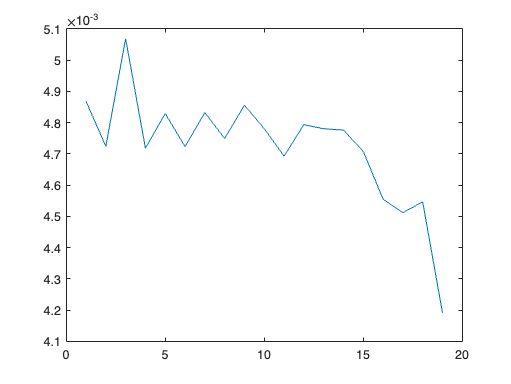


figure
plot(p2s)


mean(tau1s)

ans = 2.8744

mean(tau2s)

ans = 0.6714

mean(p1s)

ans = 0.9953

mean(p2s)

ans = 0.0047

save('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_ACh_20220722/fitting_parameters_ACh_condition.mat',...
    'tau1s','tau2s','p1s','p2s','betahats','Acq_nums','chisqs','lifetimes_collection','photoncounts','empirical_lft','mean_tau')